## l) plotting some trajectory generation

cubic_solns = cubicTraj(0, 5, 0, 0, 0, 0.5)

$$cubic\_solns = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{50}\\ -\frac{1}{125} \end{array}\right)$$

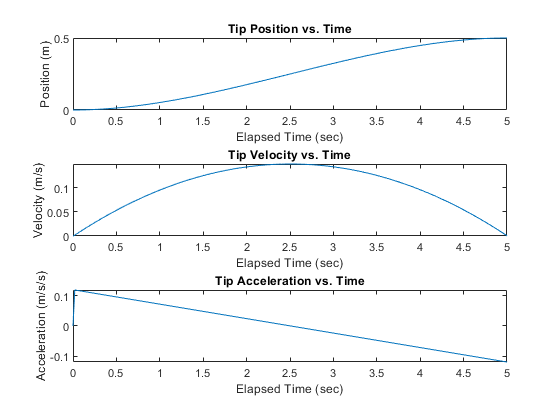


timeData = [];
posn = 0;
lastPosn = 0;
vel = 0;
lastVel = 0;
acc = 0;

posnData = [];
velData = [];
accData = [];



for ii = 0:0.01:5
    time = ii;
    posn = getInterPt(cubic_solns, time);
    vel = (posn - lastPosn)/0.01;
    acc  = (vel - lastVel)/ 0.01;
    
    lastPosn = posn;
    lastVel = vel;
    
    timeData = [timeData; time];
    posnData = [posnData; posn];
    velData = [velData; vel];
    accData = [accData; acc];
end

fig1 = figure(1);
subplot(3,1,1);
posnPlot = plot(timeData,posnData);
    xlabel('Elapsed Time (sec)');
    ylabel('Position (m)');
    title('Tip Position vs. Time');
subplot(3,1,2);
velPlot = plot(timeData,velData);
    xlabel('Elapsed Time (sec)');
    ylabel('Velocity (m/s)');
    title('Tip Velocity vs. Time');
subplot(3,1,3);
accPlot = plot(timeData,accData);
    xlabel('Elapsed Time (sec)');
    ylabel('Acceleration (m/s/s)');
    title('Tip Acceleration vs. Time');

function [coeffSolns] = cubicTraj(t0, tf, v0, vf, x0, xf)
%cubicTraj produces a trajectory using a solution to a cubic polynomial
%   consumes start time (seconds) end time (seconds),
%   start velocity (deg/s) and end velocity (deg/s)
%   start position (deg) and end position (deg)
coeffSolns = zeros(4,1,'single');

syms a0 a1 a2 a3;

eqn1 = a0 + a1*t0 + a2*t0^2 + a3*t0^3 == x0;
eqn2 = a1 + 2*a2*t0 + 3*a3*t0^2 == v0;
eqn3 = a0 + a1*tf + a2*tf^2 + a3*tf^3 == xf;
eqn4 = a1 + 2*a2*tf + 3*a3*tf^2 == vf;

[A,B] = equationsToMatrix([eqn1 eqn2 eqn3 eqn4],[a0 a1 a2 a3]);
coeffSolns = linsolve(A,B);
end

function [ thisPt ] = getInterPt( coeff_solns, thisTime )
%GETINTERPT get an interpolated point (in mm)
%   consumes a set of coeff solutions and time (in seconds)
%   produces mm the tip should be at this time
%   note: coeff_solns are the return value of cubicTraj

    a0 = coeff_solns(1);
    a1 = coeff_solns(2);
    a2 = coeff_solns(3);
    a3 = coeff_solns(4);
    
    tx = thisTime;
    
    
    thisPt = a0 + a1*tx + a2*tx^2 + a3*tx^3;
end